data = readtable(['data_reduced.csv']);

lables= data.Properties.VariableNames

lables = 1×47 cell array
    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_crystallinity'}    {'Contaminant_topology'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_viscosity'}    {'WeightImpurity'}    {'matrixE'}    {'matrixSTRENGTH'}    {'matrixStrainbreak'}    {'matrixImpact'}    {'impurityE'}    {'impuritySTRENGTH'}    {'impurityStrainbreak'}    {'impurityImpact'}    {'matrixXc'}    {'impurityXc'}    {'blendE'}    {'blendSTRENGTH'}    {'blendStrainbreak'}    {'blendImpact'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_HDPE1'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_LLDPE1'}    {'Min

lables = cell2table(lables);
lablesS = lables(1, 1:13);
lablesS2 = lables(1,28:end);
lablesE= [lablesS, lables(1,14), lables(1,18), lables(1,22:23), lablesS2];
lablesYE= lables(1,24);

12 features + %impurity

col 14 matrix E, 18 impurity E

col 22, 23 Matrix/imp XC

col 24 blendE

col 28 start of 1H (Majority and min polymers)

% E =
E =  table2array(data(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

E = 	1.0e+03 *

         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0005    0.1924    0.9529    0.0327    0.0651    0.4624         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0002    0.1924    0.9529    0.0327    0.0651    0.2918         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0001    0.1924    0.9529    0.0327    0.0651    0.2380         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020 


% standarize 
E = (E-min(E, [], 1))./range(E,1)

E =          0    0.5000         0    1.0000    1.0000    0.1667         0    1.0000    1.0000         0         0    0.6667    1.0000    0.0306    0.2976    0.4860    0.9677    0.1167         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    0.5000         0    1.0000    1.0000    0.1667         0    1.0000    1.0000         0         0    0.6667    0.4000    0.0306    0.2976    0.4860    0.9677    0.0621         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    0.5000         0    1.0000    1.0000    0.1667         0    1.0000    1.0000         0         0    0.6667    0.2000    0.0306    0.2976    0.4860    0.9677    0.0449         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    0.5000         0    1.0000    1.0000    0.1667         0    1.0000    1.0000   

Xe= [E(:,1:17), E(:,19:end)]

Xe =          0    0.5000         0    1.0000    1.0000    0.1667         0    1.0000    1.0000         0         0    0.6667    1.0000    0.0306    0.2976    0.4860    0.9677         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    0.5000         0    1.0000    1.0000    0.1667         0    1.0000    1.0000         0         0    0.6667    0.4000    0.0306    0.2976    0.4860    0.9677         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    0.5000         0    1.0000    1.0000    0.1667         0    1.0000    1.0000         0         0    0.6667    0.2000    0.0306    0.2976    0.4860    0.9677         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    0.5000         0    1.0000    1.0000    0.1667         0    1.0000    1.0000         0         0    0.6667  

Ye = E(:,18)

Ye =     0.1167
    0.0621
    0.0449
    0.0329
    0.0364
    0.0324
    0.0304
    0.0132
    0.0196
    0.0226


% E = (E - mean(E))./std(E, [], 1)
% Enum = E(:,1:end-8)


% default l= 1/n
nca = fsrnca(Xe, Ye, 'Verbose',2)


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  1.937704e-01 |   1.533e-02 |   0.000e+00 |        |   3.914e+01 |   0.000e+00 |   YES  |
|        1 |  1.615561e-01 |   1.271e-02 |   1.403e+00 |    OK  |   3.153e+01 |   1.000e+00 |   YES  |
|        2 |  1.489998e-01 |   1.089e-02 |   1.608e+00 |    OK  |   4.726e+01 |   1.000e+00 |   YES  |
|        3 |  1.381215e-01 |   6.375e-03 |   7.702e-01 |    OK  |   4.870e+01 |   1.000e+00 |   YES  |
|        4 |  1.336678e-01 |   6.778e-03 |   1.731e+00 |    OK  |   5.900e+01 |   1.000e+00 |   YES  |
|        5 |  1.309863e-01 |   1.300e-03 |   5.346e-01 |    OK  |   4.391e+01 |   1.000e+00 |   YES  

nca =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'exact'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


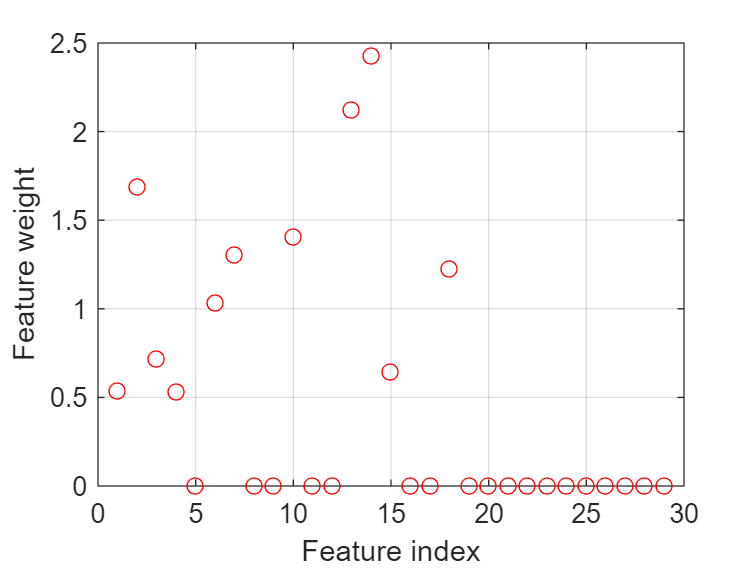

figure()
plot(nca.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')


figure
fitted = predict(nca, Xe)

fitted =     0.1901
    0.0586
    0.0407
    0.0352
    0.0336
    0.0327
    0.0313
    0.0721
    0.0385
    0.0347


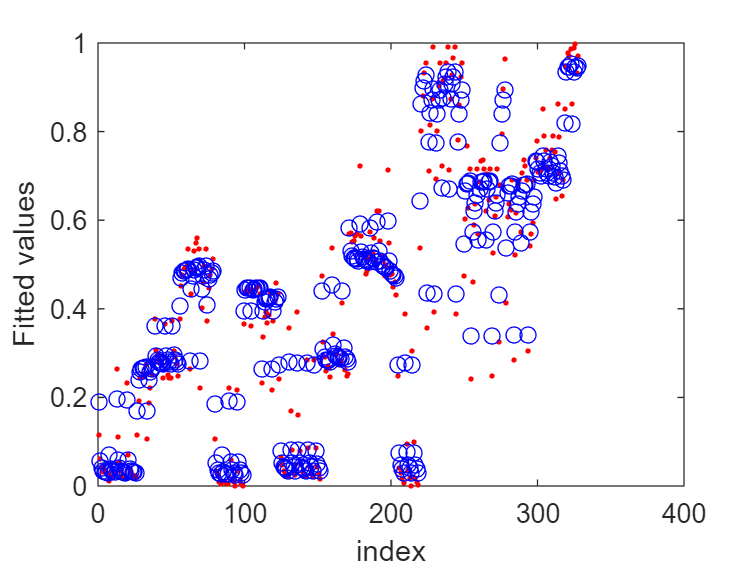

plot(Ye,'r.')
hold on
plot(fitted,'bo')
xlabel('index')
ylabel('Fitted values')

regression is too strong 

% nca = fsrnca(Xe, Ye, 'Verbose',2,'Lambda')


cv        = cvpartition(Ye,'kfold',5);

numtestsets   = cv.NumTestSets;
lambdavalues  = linspace(0.000001/length(Ye),1/length(Ye),20); 
lossvalues    = zeros(length(lambdavalues),numtestsets);

% mape = @(y, yp) 1/328 * sum((y - yp) / y) * 100
ape = @(y, yp) ((y - yp) / y )* 100

ape = function_handle with value:
    @(y,yp)((y-yp)/y)*100


for i = 1:length(lambdavalues)                
    for k = 1:numtestsets
        
        % Extract the training set from the partition object
        Xtrain = Xe(cv.training(k),:);
        Ytrain = Ye(cv.training(k),:);
        
        % Extract the test set from the partition object
        Xtest = Xe(cv.test(k),:);
        Ytest = Ye(cv.test(k),:);
        
        % Train an nca model for classification using the training set
        ncaMdl = fscnca(Xtrain,Ytrain,'FitMethod','exact', ...
            'Solver','lbfgs','Lambda',lambdavalues(i),  'LossFunction',ape);
        
        % Compute the classification loss for the test set using the nca
        % model
        lossvalues(i,k) = loss(nca,Xtest,Ytest, ...
            'LossFunction','mse');   
   
    end                          
end

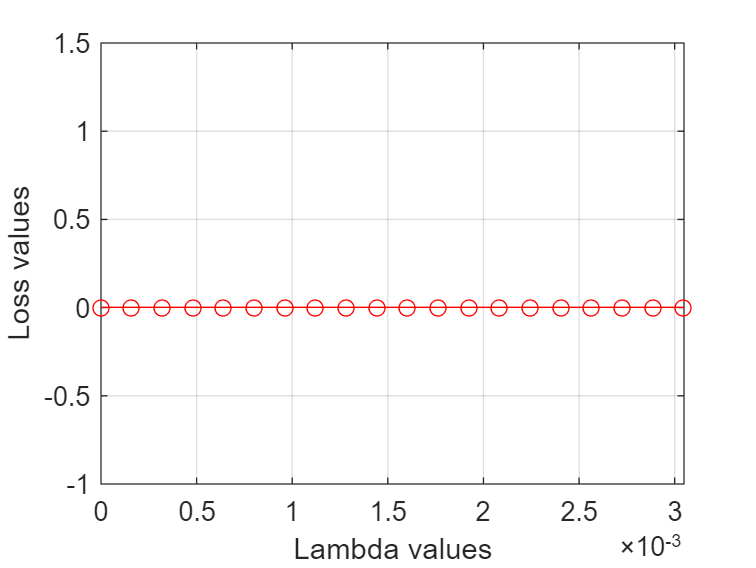

figure
plot(lambdavalues,mean(lossvalues,2),'ro-')
xlabel('Lambda values')
ylabel('Loss values')
grid on

[idx,scores] = fsrftest(Xe,Ye);
% he values in scores are the negative logs of the p-values
 find(isinf(scores)) 


ans =

  1×0 empty double row vector



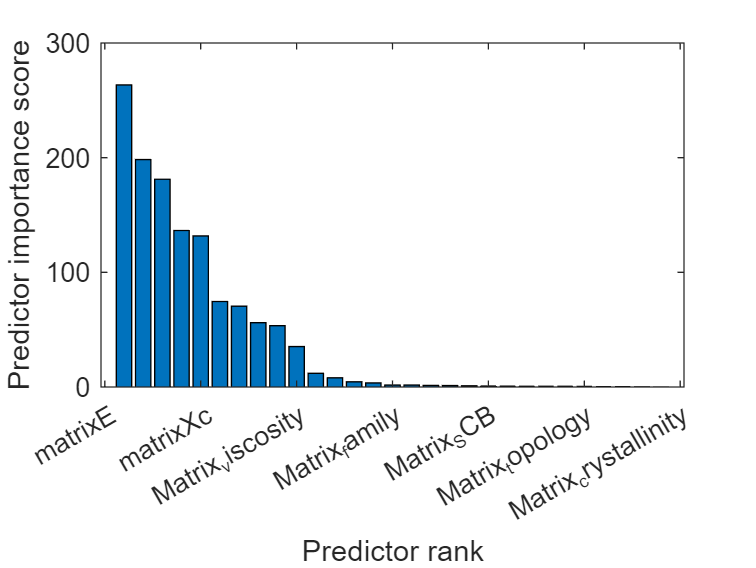

% no neg pvalues, meaning null hypothesis??
bar(scores(idx))
xticks('auto')
xticklabels(table2cell(lablesE(1,idx)))

xlabel('Predictor rank')
ylabel('Predictor importance score')


relevant_features_names = lablesE(1,idx);
relevant_features = E(:,idx);

[~,idx] = min(mean(lossvalues,2));
bestlambda = lambdavalues(idx)

bestlambda = 3.0488e-09

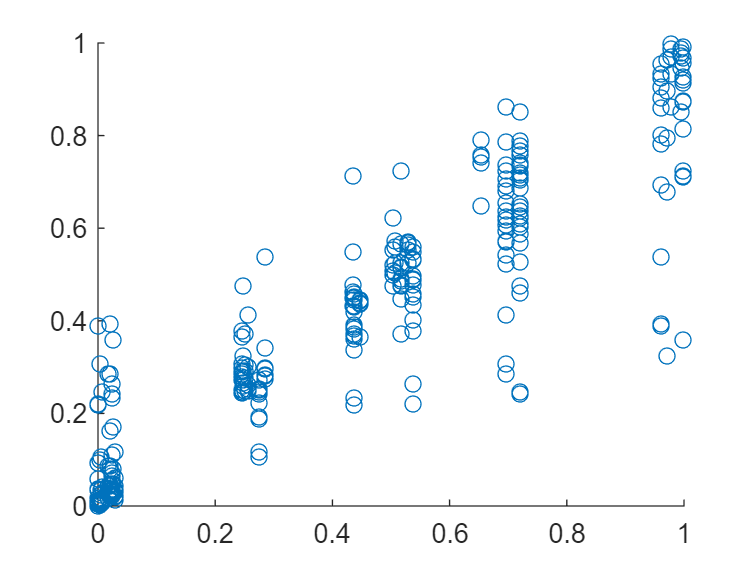

scatter(relevant_features(:,1), Ye)

% since 2022. upadrteee
[idx, scores] = fsrmrmr(Xe,Ye);

Unrecognized function or variable 'fsrmrmr'.